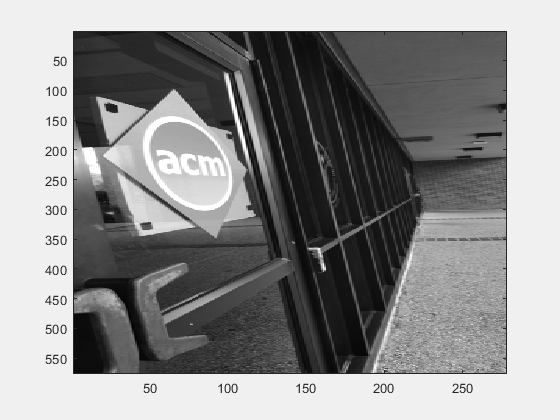

%PART 1 - Reading CSE building image and coordinate points of the tilted ACM rectange
figure('Name','Select 4 corners of ACM rectangle to be corrected');
img1 = imread('\\Client\E$\Computer Vision\Planar distortion\img1.jpg');
img12D=[];
img1 = rgb2gray(img1);
img1 = imresize(img1, 0.125);
colormap(gray(256));
image(img1); drawnow; hold on;
for i=1:4
[x, y]=ginput(1);
v=[x;y];
img12D=[img12D v];
end

% Part 1 - Correcting Planar distortion


imgb2D=[];
[rowDistorted,colDistorted] = size(img1);
figure('Name','Part1 - Select expected correct coordinates on blank image');
blankImage = 255*ones(2*rowDistorted,2*colDistorted);
colormap(gray(256));
% Select points in blank image to correct distortion
image(blankImage); drawnow; hold on;
    for i=1:4
    [x, y]=ginput(1);
    v=[x;y];
    imgb2D=[imgb2D v];
end

P = [];
w = 1;
for n = 1:4
    A = zeros(1,3);
    c1 = -w*imgb2D(1,n);
    c2 = -w*imgb2D(2,n);
    c3 = -w*1;
    c5 = img12D(2,n)*imgb2D(1,n);
    c6 = img12D(2,n)*imgb2D(2,n);
    c7 = img12D(2,n)*1;
    R1 = [A c1 c2 c3 c5 c6 c7];
    c9 = img12D(1,n)*imgb2D(1,n);
    c10 = img12D(1,n)*imgb2D(2,n);
    c11 = img12D(1,n)*1;
    R2 = [c1 c2 c3 A c9 c10 c11];
    P = [P;R1;R2];
end
[U,S,V] = svd(P);
H = V(:,[end]);
Hn = (reshape(V(:,9), 3, 3)).';
imgPart1 = zeros(2*rowDistorted,2*colDistorted);
count = 0;
    for i= 1:2*colDistorted
        for j = 1:2*rowDistorted
            mat = [i;j;1];
            orI = Hn*mat;  
            resR = double(orI(1))/double(orI(3));
            resC = double(orI(2))/double(orI(3));
            
           if (floor(resR) > 0 && floor(resR) <= colDistorted && floor(resC) > 0 && floor(resC) <= rowDistorted) && (ceil(resR) > 0 && ceil(resR) <= colDistorted && ceil(resC) > 0 && ceil(resC) <= rowDistorted-1)
            count = count + 1;
            inpR = round(i);
            inpC = round(j);
            imgPart1(inpC,inpR) = img1(floor(resC),floor(resR));
            
           end
        end
    end
disp('Part 1 - Remove planar distortion')

Part 1 - Remove planar distortion


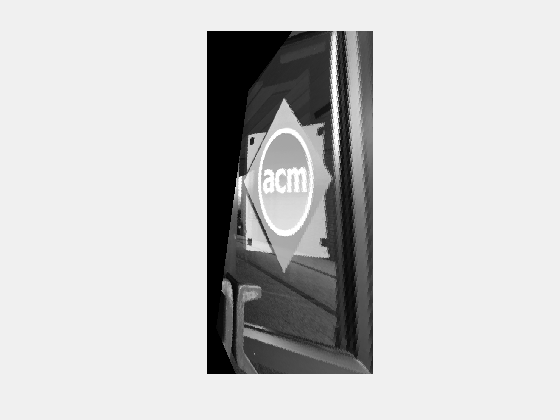

imshow(imgPart1,[]);

## PART 2: Generating two new perspective

Part 2 - new Perspective1


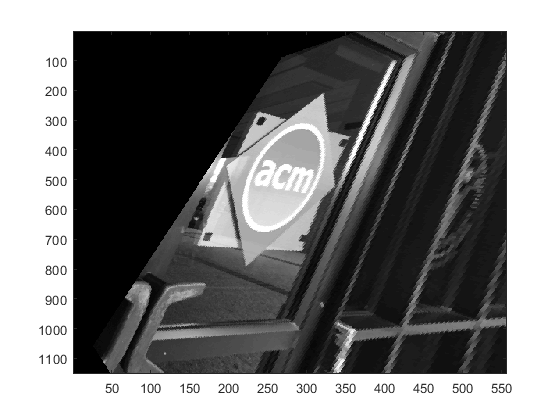

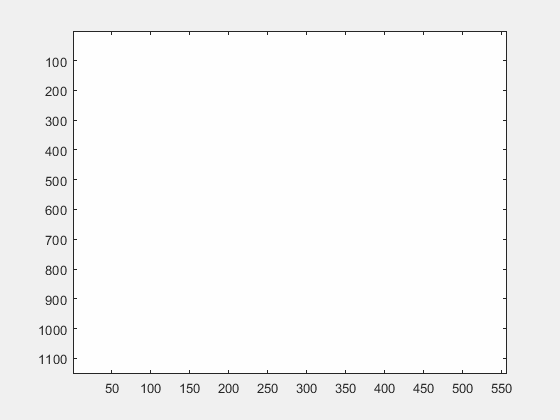

Part 2 - new Perspective2


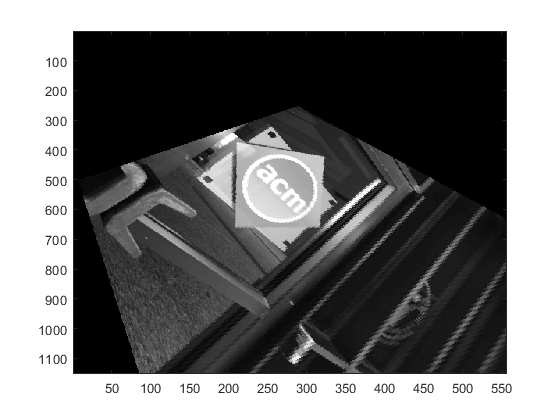

for perspective = 1:2
    imgb2D= [];
    % Select points on Blank image to generate different perspectives of
    % CSE building image
    figure('Name', 'Select 4 points on blank image to set new perspective of the input image');
    colormap(gray(256));
    image(blankImage); drawnow; hold on;
    for i=1:4
        [x, y]=ginput(1);
        v=[x;y];
        imgb2D=[imgb2D v];
    end
    P = [];
    w = 1;
    for n = 1:4
        A = zeros(1,3);
        c1 = -w*imgb2D(1,n);
        c2 = -w*imgb2D(2,n);
        c3 = -w*1;
        c5 = img12D(2,n)*imgb2D(1,n);
        c6 = img12D(2,n)*imgb2D(2,n);
        c7 = img12D(2,n)*1;
        R1 = [A c1 c2 c3 c5 c6 c7];
        c9 = img12D(1,n)*imgb2D(1,n);
        c10 = img12D(1,n)*imgb2D(2,n);
        c11 = img12D(1,n)*1;
        R2 = [c1 c2 c3 A c9 c10 c11];
        P = [P;R1;R2];
    end
    [U,S,V] = svd(P);
    Hn = (reshape(V(:,9), 3, 3)).';
    [r,c] = size(img1);
    % Creating and filling the new perspective image with right pixel and
    % also taking care of holes
    imagePart2 = zeros(2*r,2*c);
    for i= 1:2*c
        for j = 1:2*r
            mat = [i;j;1];
            orI = Hn*mat;  
            resR = double(orI(1))/double(orI(3));
            resC = double(orI(2))/double(orI(3));
            
           if (floor(resR) > 0 && floor(resR) <= colDistorted && floor(resC) > 0 && floor(resC) <= rowDistorted) && (ceil(resR) > 0 && ceil(resR) <= colDistorted && ceil(resC) > 0 && ceil(resC) <= rowDistorted-1)
            count = count + 1;
            inpR = round(i);
            inpC = round(j);
            imagePart2(inpC,inpR) = img1(floor(resC),floor(resR));
            
           end
        end
    end
    disp(['Part 2 - new Perspective', num2str(perspective)])
    figure, imagesc(imagePart2), colormap gray ;
end